%dec
clear
syms y t t2 n;
N = 32;
% N = 64;
% a=1.2;b=0;
% a=0;b=1.6;
a=1.2; b=1.8;
T=200;
dt=1;
% t0=[0, 10, 20, 40, 60, 80, 100];
t0= 0;

% [D,~]=cheb(N);
[x, D, D2, D4, w] =finitediff(N,2);

h=eye(size(D));
h1=eye(size(D));
k2=(a^2+b^2)*h;
k=((a^2+b^2)^0.5)*h;
% w1=w.^0.5;
W=sqrt(diag(w));
d=D+k;
WW=W*d;

%v
% V=[WW,zeros(N-1,N-1);zeros(N-1,N-1),W]; %126*126
V=[WW,zeros(N-2,N-2);zeros(N-2,N-2),W]; %126*126
c=D2-k2;

Cn=0;
NN=100;
k0 = 0.1;
Re= 500;
g=1-exp(-k0.*t); %Acc
g=exp(-k0.*t); %Dec
an = (pi*n).^2./Re;  %lately
m=diff(g,t);
a1=subs(m,t,0);
m2=diff(m,t);
a2=subs(m2,t,t2);
e=exp(an.*t2);
a3=simplify(e*a2);
a4=simplify(int(a3, t2, 0, t),'Steps',200);
a5=a4+a1;
aa=-2.*Re.*(-1).^n./(pi.*n).^3.*(a5)+Cn;
a6=simplify(aa.*exp(-an.*t).*sin(n.*y.*pi),'Steps',100);
b1=Re./6.*m.*(y.^3-y);
b2=g.*y;
bb=b1+b2;
a7 = 0;
for ii = 1:NN
    a7 = a7 + subs(a6, n, ii);
end
U=a7+bb;
mm=diff(U);
mm2=diff(mm);
% U_yi = (subs(U, y, yi(2:N)));
% m_yi = (subs(mm, y, yi(2:N)));
% m2_yi = (subs(mm2, y, yi(2:N)));

U_yi = (subs(U, y, x));
m_yi = (subs(mm, y, x));
m2_yi = (subs(mm2, y, x));
U_yi_function = matlabFunction(U_yi);
m_yi_function = matlabFunction(m_yi);
m2_yi_function = matlabFunction(m2_yi);

%speeding code
o=(1/(1i*Re))*(D4-2*D2*k2+k2*k2);
oo=-inv(c);
ooo=(1/(1i*Re))*c;
max_eigA = cell(1, length(t0)); % Cell array to store max eigenvalues for each t0
min_eigA = cell(1, length(t0)); % Cell array to store max eigenvalues for each t0

%A
for j = 1:length(t0)
    t_steps = (T-t0(j))/dt;
    ttt = linspace(0, T-t0(j), t_steps);
    G = zeros(1, t_steps);
    AA = eye(size(V));
    max_eig_current = zeros(1, t_steps);

    %U_value
    for i = 1:t_steps  %step
        t_value=t0(j)+i*dt;
        U_yi_value = diag(U_yi_function(t_value));% t from t0 to t0+T
        m_yi_value = diag(m_yi_function(t_value));
        m2_yi_value = diag(m2_yi_function(t_value));
        %L
        Los=oo*(o-(a*h1)*U_yi_value*c+(a*h1)*m2_yi_value);%!
        Lsq=(a*h1)*U_yi_value-ooo;
        Lc=(b*h1)*m_yi_value;%diag
        L_value=[Los,zeros(N-2,N-2);Lc,Lsq];
        L=V*(-1i*L_value)/V;%new added
        A(:, :, i) = L;
        [eigA] = eig(L);
        % Store maximum eigenvalue magnitude
        max_eig_current(i) = max(real(eigA));
        %L_value=double(L);
        AA =expm(-1i*L_value*dt)*AA;
        AA_store{i} = AA;   % store propagator at this time
        %G
        gh1=double(V*AA/V);
        G(i)=norm(gh1)^2;
    end
    G_storage{j} = G;
    max_trans=max(G);
    max_eigA{j} = max_eig_current;
    %     min_eigA{j} = min_eig_current;
    plot(ttt,G,'-');
    hold on
end

xlim([0 200]);
set(gca, 'YScale', 'log');
% ylim([10^-1 10^3]);
set(gca, 'YTick', [10^-1 10^1 10^3 10^5 10^7]);
snap_times = [0, 5, 10, 15, 20, 50];
% M = size(V, 1) / 2;

if b == 0
    Lx = 2*pi/a;
    nx = 32;
    x_domain = linspace(0, Lx, nx);
    y_nodes = x(:);      % 62 interior Chebyshev nodes
    M = length(y_nodes);
    [X, Y] = meshgrid(x_domain, y_nodes);
end

if a == 0
    Lz = 2*pi/b;
    nz = 32;
    z_domain = linspace(0, Lz, nz);
    y_nodes = x(:);      % 62 interior Chebyshev nodes
    M = length(y_nodes);
    [Z, Y] = meshgrid(z_domain, y_nodes); % Meshgrid for the spanwise plane
end

if a ~= 0 && b ~= 0
    Lx = 2*pi/a;
    nx = 32;
    x_domain = linspace(0, Lx, nx);
    Lz = 2*pi/b;
    nz = 32;
    z_domain = linspace(0, Lz, nz);
    y_nodes = x(:);      % 62 interior Chebyshev nodes
    M = length(y_nodes);
%     [Z, Y, X] = meshgrid(z_domain, y_nodes, x_domain); 
end

%% Energy of Optimal Perturbation

[max_G, idx_max] = max(G);
t_opt = t0 + idx_max * dt;
fprintf('Maximum growth G = %.2f at t = %.2f\n', max_G, t_opt);

Maximum growth G = 61.15 at t = 11.00


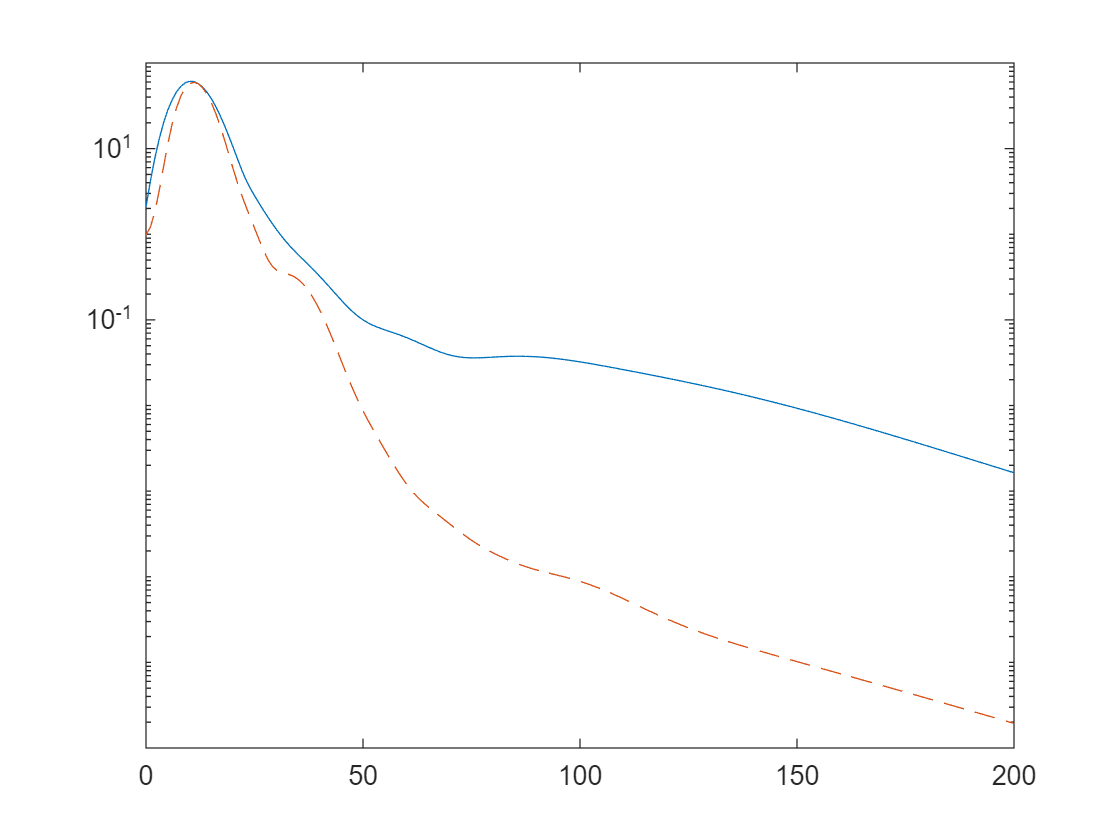


% SVD at the optimal time index
[U_svd, S_svd, V_svd] = svd(AA_store{idx_max});

q0_energy = V_svd(:, 1); % Optimal IC
% q0_energy = randn(size(V_svd, 1), 1);
% q0_energy = randn(size(V,1), 1) + 1i*randn(size(V,1), 1);

Gp = zeros(size(ttt));
for i = 1:t_steps
    % Evolve vS1 to time t using the stored propagator AA_store
    vt = (V * AA_store{i} / V) * q0_energy;
    % Gp is the energy of this specific perturbation at time t
    Gp(i) = norm(vt)^2;
end

plot(ttt,Gp,'--');
hold on
xlim([0 200]);
set(gca, 'YScale', 'log');
% ylim([10^-1 10^3]);
set(gca, 'YTick', [10^-1 10^1 10^3 10^5 10^7]); %



figure;
for s = 1:length(snap_times)
    ts = snap_times(s);
    q_t_energy = q0_energy;


    if ts > 0
        nsteps_snap = round(ts/dt);
        for ii = 1:nsteps_snap
            t_i = t0 + ii*dt;

            % Build operator
            U_val  = diag(U_yi_function(t_i));
            m_val  = diag(m_yi_function(t_i));
            m2_val = diag(m2_yi_function(t_i));


            Los = oo * (o - a*U_val*c + a*m2_val);
            Lsq = a*U_val - ooo;
            Lc  = b*m_val;
            L_mat = [Los, zeros(M,M); Lc, Lsq];
            L_energy = V*(-1i*L_mat)/V;

            q_t_energy = expm(-1i*L_mat*dt)*q_t_energy;
            %             q_t_energy_store{i} = q_t_energy;

            if any(isnan(q_t_energy)) || any(isinf(q_t_energy))
                error('Blow-up at step %d, t=%g', ii, t_i);
            end
        end
    end

    q_phys = q_t_energy;
    v_interior = q_phys(1:M);  % M = N-2
    eta_interior = q_phys(M+1:end);
    psi_interior = 1i * v_interior * a;
    u_hat_interior = (D * psi_interior(:) - 1i* eta_interior*b) * (1/(a^2+b^2));  % size M = N-2
    w_hat_interior = (1i*a * eta_interior + 1i*b*D*v_interior) * (1/(a^2+b^2));    % 64×1
    y_interior = x;  % x = interior Chebyshev nodes (N-2)

    if a ~= 0 && b ~= 0
        Psi_3D = zeros(M, nz, nx);
        P_3D = zeros(M, nz, nx);
        dUdy = m_yi_function(ts);
        for i = 1:nx
            for k = 1:nz
                phase = exp(1i * a * x_domain(k) + 1i * b * z_domain(k));
                u_l = real(u_hat_interior .* phase);
                u_l_3D(:, k, i) = real(u_hat_interior .* phase);  % store as column
                v_l = real(v_interior .* phase);
                v_l_3D(:, k, i) = real(v_interior .* phase);
                w_l_3D(:, k, i) = imag(w_hat_interior .* phase);
                Psi_3D(:, k, i) = real(1i * v_interior * phase/ sqrt(a^2 + b^2));
%                 P_3D(:, k, i) = -(u_l .* v_l) .* dUdy(:);
            end
        end
        U_prof = U_yi_function(ts);
        g_current = exp(-k0 * ts);
        U_full   = [-g_current; U_prof(:); +g_current];
        slice_z_idx = 1; % Corresponds to z = z_domain(1)
%         P_2D  = squeeze(P_3D(:, slice_z_idx, :));   % Size becomes [M, nx]
        Psi_2D = squeeze(Psi_3D(:, slice_z_idx, :)); % Size becomes [M, nx]
        [X, Y] = meshgrid(x_domain, y_nodes);
        % Subplot Generation
        ax1 = subplot(3, 2, s);
        hold on;
        % Production Contour (Normalized)
%         P_norm = P_2D / max(abs(P_3D(:)));
%         contourf(X, Y, -P_norm, 50, 'LineStyle', 'none');
        % Streamlines
        contour(X, Y, Psi_2D, 10, 'k', 'LineWidth', 0.5);
        caxis([-1 1]);                 % symmetric around zero
        colormap(ax1, bluewhitered);
        colorbar(ax1,'Location','eastoutside');
        set(ax1,'FontSize',13,'Box','on');
        title(['t = ', num2str(ts)]);
        xlabel('x'); ylabel('y');
        axis tight;

        if ts == 0
            % Save only the initial perturbation state
            save('perturbation.mat', 'u_l_3D', 'v_l_3D', 'w_l_3D','z_domain', 'Y', 'X', 't_opt');
            fprintf('Initial perturbation saved at t = 0\n');
        end
    end

    if a == 0
        Psi_2D = zeros(M, nz);
        P_2D = zeros(M, nz);
        dUdy = m_yi_function(ts);
        for k = 1:nz
            phase = exp(1i * b * z_domain(k));
            u_l = real(u_hat_interior .* phase);
            u_l_2D(:, k) = real(u_hat_interior .* phase);  % store as column
            v_l = real(v_interior .* phase);
            v_l_2D(:, k) = real(v_interior .* phase);
            w_l_2D(:, k) = imag(w_hat_interior .* phase);
            Psi_2D(:, k) = real(1i * v_interior * b * phase);
            P_2D(:, k) = -(u_l .* v_l) .* dUdy(:);
        end
        U_prof = U_yi_function(ts);
        g_current = exp(-k0 * ts);
        U_full   = [-g_current; U_prof(:); +g_current];
        % Subplot Generation
        ax1 = subplot(3, 2, s);
        hold on;
        % Production Contour (Normalized)
        P_norm = P_2D / max(abs(P_2D(:)));
        contourf(Z, Y, -P_norm, 50, 'LineStyle', 'none');
        % Streamlines
        contour(Z, Y, Psi_2D, 10, 'k', 'LineWidth', 0.5);
        caxis([-1 1]);                 % symmetric around zero
        colormap(ax1, bluewhitered);
        colorbar(ax1,'Location','eastoutside');
        set(ax1,'FontSize',13,'Box','on');
        title(['t = ', num2str(ts)]);
        xlabel('x'); ylabel('y');
        axis tight;

        if ts == 0
            % Save only the initial perturbation state
            save('perturbation.mat', 'u_l_2D', 'v_l_2D', 'w_l_2D','Z', 'Y', 't_opt');
            fprintf('Initial perturbation saved at t = 0\n');
        end
    end

    if b == 0

        Psi_2D = zeros(M, nx);
        P_2D = zeros(M, nx);
        dUdy = m_yi_function(ts);
        for k = 1:nx
            phase = exp(1i * a * x_domain(k));
            u_l = real(u_hat_interior .* phase);
            u_l_2D(:, k) = real(u_hat_interior .* phase);  % store as column
            v_l = real(v_interior .* phase);
            v_l_2D(:, k) = real(v_interior .* phase);
            w_l_2D(:, k) = imag(w_hat_interior .* phase);
            Psi_2D(:, k) = real(psi_interior * phase);
            P_2D(:, k) = -(u_l .* v_l) .* dUdy(:);
        end
        U_prof = U_yi_function(ts);
        g_current = exp(-k0 * ts);
        U_full   = [-g_current; U_prof(:); +g_current];
        % Subplot Generation
        ax1 = subplot(3, 2, s);
        hold on;
        % Production Contour (Normalized)
        P_norm = P_2D / max(abs(P_2D(:)));
        contourf(X, Y, -P_norm, 50, 'LineStyle', 'none');
        % Streamlines
        contour(X, Y, Psi_2D, 10, 'k', 'LineWidth', 0.5);
        caxis([-1 1]);                 % symmetric around zero
        colormap(ax1, bluewhitered);
        %     colormap(ax1);
        colorbar(ax1,'Location','eastoutside');
        %     caxis(ax1,[-0.25 0.25]);
        set(ax1,'FontSize',13,'Box','on');
        title(['t = ', num2str(ts)]);
        xlabel('x'); ylabel('y');
        axis tight;

        if ts == 0
            % Save only the initial perturbation state
            save('perturbation.mat', 'u_l_2D', 'v_l_2D', 'w_l_2D','X', 'Y', 't_opt');
            fprintf('Initial perturbation saved at t = 0\n');
        end


    end

end


function [x,w] = clencurt(N)
theta = pi*(0:N)'/N; x = cos(theta);
w = zeros(1,N+1); ii = 2:N; v = ones(N-1,1);
if mod(N,2)==0
w(1) = 1/(N^2-1); w(N+1) = w(1);
for k=1:N/2-1, v = v - 2*cos(2*k*theta(ii))/(4*k^2-1); end
v = v - cos(N*theta(ii))/(N^2-1);;
else
w(1) = 1/N^2; w(N+1) = w(1);
for k=1:(N-1)/2, v = v - 2*cos(2*k*theta(ii))/(4*k^2-1); end
end
w(ii) = 2*v/N;
end


function [x, D1, D2, D4,w] =finitediff(N,L)

%Differentiation matrix using finite difference scheme.
%This is suitable for Dirichlet boundary condition v(x=L/2)=v(x=-L/2)=0 at
%the boundary and Neumann boundary condition v'(x=L/2)=v'(x=-L/2)=0. 

dx=L/N;%get grid spacing. 

x=linspace(-L/2,L/2,N);%get the grid point location

x=x(2:end-1); %delete the first and last points that are zero. 

w=dx*ones(1,N-2);%integration weighting 

N_diff=N-2;%The size of differentiation matrices

%First order derivative based on central difference
%f'(x_i)=(f(x_{i+1})-f(x_{i-1})/(2*dx)
%We also use the boundary condition that x_0=x_N=0
D1_stencil=diag(-1*ones(1,N_diff-1),1)+diag(ones(1,N_diff-1),-1);
D1=D1_stencil/(2*dx);

%Second order derivative based on central difference
%f''(x_i)=(f(x_{i+1})-2f(x_i)+f(x_{i-1})/(dx^2)
%We also use the boundary condition that x_0=x_N=0
D2_stencil=(diag(-2*ones(1,N_diff))+diag(ones(1,N_diff-1),1)+diag(ones(1,N_diff-1),-1));
D2=D2_stencil/dx^2;

%Forth order derivative based on central difference
%f''''(x_i)=(f(x_{i+2})-4f(x_{i+1})+6f(x_i)-4f(x_{i-1})+f(x_{i-2})/(dx^4)
%This differentiation matrix only go through x_1 up to x_{N-1}
D4_stencil=(diag(6*ones(1,N_diff))+diag(-4*ones(1,N_diff-1),1)+diag(-4*ones(1,N_diff-1),-1)...
    + diag(ones(1,N_diff-2),2)+diag(ones(1,N_diff-2),-2));

%Here, we use the Neumann boundary condition that x_0'=x_N'=0
%such that x_1=x_{-1} and x_{N-1}=x_{N+1} for the ghost points. Then we
%also use the condition x_0 and x_N=0 to express all values based on x_1 up
%to x_{N-1}
D4_stencil(1,1)=D4_stencil(1,1)+1;
D4_stencil(end,end)=D4_stencil(end,end)+1;

D4=D4_stencil/dx^4;

end

function newmap = bluewhitered(m)
%BLUEWHITERED   Blue, white, and red color map.
%   BLUEWHITERED(M) returns an M-by-3 matrix containing a blue to white
%   to red colormap, with white corresponding to the CAXIS value closest
%   to zero.  This colormap is most useful for images and surface plots
%   with positive and negative values.  BLUEWHITERED, by itself, is the
%   same length as the current colormap.
%
%   Examples:
%   ------------------------------
%   figure
%   imagesc(peaks(250));
%   colormap(bluewhitered(256)), colorbar
%
%   figure
%   imagesc(peaks(250), [0 8])
%   colormap(bluewhitered), colorbar
%
%   figure
%   imagesc(peaks(250), [-6 0])
%   colormap(bluewhitered), colorbar
%
%   figure
%   surf(peaks)
%   colormap(bluewhitered)
%   axis tight
%
%   See also HSV, HOT, COOL, BONE, COPPER, PINK, FLAG, 
%   COLORMAP, RGBPLOT.


if nargin < 1
   m = size(get(gcf,'colormap'),1);
end


bottom = [0 0 0.5];
botmiddle = [0 0.5 1];
middle = [1 1 1];
topmiddle = [1 0 0];
top = [0.5 0 0];

% Find middle
lims = get(gca, 'CLim');

% Find ratio of negative to positive
if (lims(1) < 0) & (lims(2) > 0)
    % It has both negative and positive
    % Find ratio of negative to positive
    ratio = abs(lims(1)) / (abs(lims(1)) + lims(2));
    neglen = round(m*ratio);
    poslen = m - neglen;
    
    % Just negative
    new = [bottom; botmiddle; middle];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, neglen);
    newmap1 = zeros(neglen, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap1(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
    % Just positive
    new = [middle; topmiddle; top];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, poslen);
    newmap = zeros(poslen, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
    % And put 'em together
    newmap = [newmap1; newmap];
    
elseif lims(1) >= 0
    % Just positive
    new = [middle; topmiddle; top];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, m);
    newmap = zeros(m, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
else
    % Just negative
    new = [bottom; botmiddle; middle];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, m);
    newmap = zeros(m, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
end
end
